Settings

Alles löschen

clear
clc

LaTex-Interpreter als Standard für Grafiken setzen

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Schriftgröße für Grafiken setzen

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Verzeichnis wechseln (in Verzeichnis des Live-Skripts)

cd(fileparts(matlab.desktop.editor.getActiveFilename))
load('Aufgabe1.mat')



omega_log = logspace(6,7, 1001);
Z_num  = 1 ./((1j * omega_log * C_p_num) + 1 ./ ((1j * omega_log * L_num) + R_num + 1 ./ (1j * omega_log * C_num)));
G = Z_num;
G_dB = 20 * log10(abs(G));
G_arg = unwrap(angle(G)) * 180 / pi;

Grafische Darstellung

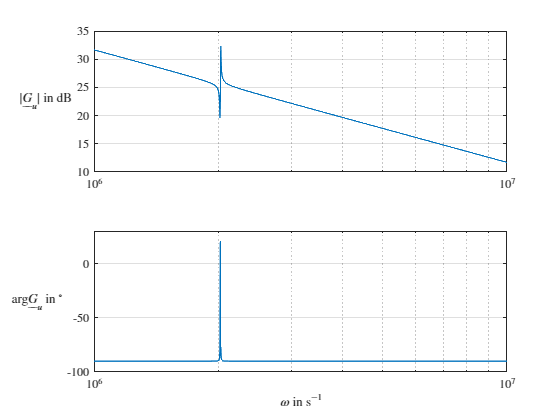

figure
tiledlayout(2, 1)

pl1 = nexttile;
semilogx(omega_log, G_dB) 

hold('on')
grid('on')
ylabel('$|\underline G_{u}|$ in dB')
set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')

pl2 = nexttile;
semilogx(omega_log, G_arg)
hold('on')
grid('on')
xlabel('$\omega$ in s$^{-1}$')
ylabel('arg{$\underline G_u$} in $^\circ$')
set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')
ylim([-100 , 30])

omega_log = logspace(6.3, 6.315, 1001);
Z_num  = 1 ./((1j * omega_log * C_p_num) + 1 ./ ((1j * omega_log * L_num) + R_num + 1 ./ (1j * omega_log * C_num)));
G = Z_num;
G_dB = 20 * log10(abs(G));
G_arg = unwrap(angle(G)) * 180 / pi;

Da in der obrigen Darstellung nicht viel erkennbar ist wird der Frequenzbereich weiter eingeschränkt, zudem werden die Resonanzfrequenzen eingezeichnet 

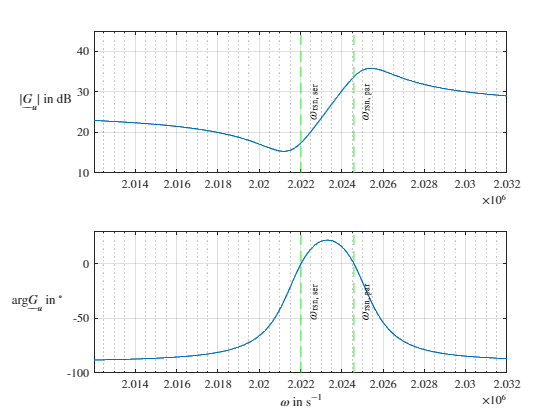

figure
tiledlayout(2, 1)

pl1 = nexttile;
semilogx(omega_log, G_dB) 

hold('on')
grid('on')
ylabel('$|\underline G_{u}|$ in dB')
xline(omega_rsn_num_ser, '--g', '$\omega_{\text{rsn, ser}}$', 'LineWidth', 1, 'LabelHorizontalAlignment', 'right', 'LabelVerticalAlignment', 'middle', 'LabelColor', 'k', 'Interpreter', 'latex');
xline(omega_rsn_num_par, '--g', '$\omega_{\text{rsn, par}}$', 'LineWidth', 1, 'LabelHorizontalAlignment', 'right', 'LabelVerticalAlignment', 'middle', 'LabelColor', 'k', 'Interpreter', 'latex');
xlabel('$\omega$ in s$^{-1}$')
set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')

pl2 = nexttile;
semilogx(omega_log, G_arg)
hold('on')
grid('on')
xlabel('$\omega$ in s$^{-1}$')
ylabel('arg{$\underline G_u$} in $^\circ$')
xline(omega_rsn_num_ser, '--g', '$\omega_{\text{rsn, ser}}$', 'LineWidth', 1, 'LabelHorizontalAlignment', 'right', 'LabelVerticalAlignment', 'middle', 'LabelColor', 'k', 'Interpreter', 'latex');
xline(omega_rsn_num_par, '--g', '$\omega_{\text{rsn, par}}$', 'LineWidth', 1, 'LabelHorizontalAlignment', 'right', 'LabelVerticalAlignment', 'middle', 'LabelColor', 'k', 'Interpreter', 'latex');
set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')
nexttile(1)
xlim([omega_rsn_num_ser - 10e3, omega_rsn_num_ser + 10e3])
ylim([10 , 45])
nexttile(2)
xlim([omega_rsn_num_ser - 10e3, omega_rsn_num_ser + 10e3])
ylim([-100 , 30])

Darstellung der Bandbreiten - Serienresonanz

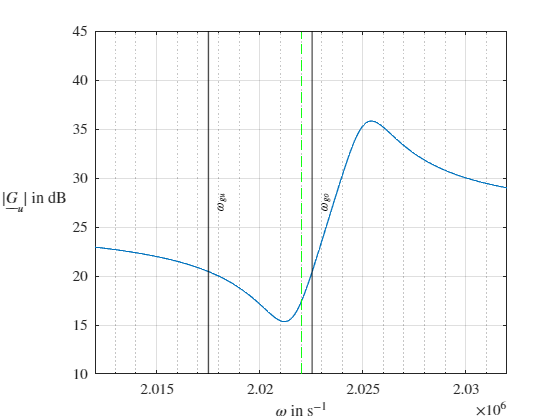

figure

semilogx(omega_log, G_dB) 

hold('on')
grid('on')
ylabel('$|\underline G_{u}|$ in dB')
xlabel('$\omega$ in s$^{-1}$')
xline(omega_rsn_num_ser, '--g');
xline(omega_gu_s, 'k', '$\omega_{gu}$', 'LineWidth', 1, 'LabelHorizontalAlignment', 'right', 'LabelVerticalAlignment', 'middle', 'LabelColor', 'k', 'Interpreter', 'latex');
xline(omega_go_s, 'k', '$\omega_{go}$', 'LineWidth', 1, 'LabelHorizontalAlignment', 'right', 'LabelVerticalAlignment', 'middle', 'LabelColor', 'k', 'Interpreter', 'latex');

set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')
xlim([omega_rsn_num_ser - 10e3, omega_rsn_num_ser + 10e3])
ylim([10 , 45])

Darstellung der Bandbreiten - Parallelresonanz

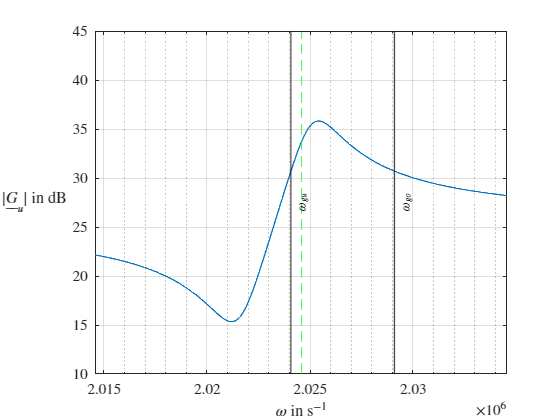

figure

semilogx(omega_log, G_dB) 

hold('on')
grid('on')
ylabel('$|\underline G_{u}|$ in dB')
xlabel('$\omega$ in s$^{-1}$')
xline(omega_rsn_num_par, '--g');
xline(omega_gu_p, 'k', '$\omega_{gu}$', 'LineWidth', 1, 'LabelHorizontalAlignment', 'right', 'LabelVerticalAlignment', 'middle', 'LabelColor', 'k', 'Interpreter', 'latex');
xline(omega_go_p, 'k', '$\omega_{go}$', 'LineWidth', 1, 'LabelHorizontalAlignment', 'right', 'LabelVerticalAlignment', 'middle', 'LabelColor', 'k', 'Interpreter', 'latex');

set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')
xlim([omega_rsn_num_par - 10e3, omega_rsn_num_par + 10e3])
ylim([10 , 45])